# 2 Motor Step Response Experiment

#### Demo 1 for SEED Lab

Alex Curtis

This script will find transfer functions for both motors using step response data, and find eventually create a controller to make sure the robot moves in a straight line.

This script runs the step response experiment I created in stepResponse.ino, interperets the data, makes some beautiful plots, determines an accurate transfer function for the motor, and tunes a PI controller to desired specifications. 

*Upload the stepResponse code to the Arduino before running.*

#### Clear previous workspace data

clear dataTable dataArray

#### Automatically find the port the Arduino is connected to

allPorts = serialportlist;  % list of all available ports
pat = "/dev/cu.usbmodem";   % text to look for

% logical array of matching ports
matchingPorts = startsWith(allPorts, pat);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard);

#### Tell the Arduino to start the forward velocity experiment (#1)

disp('Starting forward velocity experiment in Arduino')

Starting forward velocity experiment in Arduino


writeline(ard,"1"); % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end

clear newData k; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

% Create a table to store the data
dataTable = array2table(dataArray,"VariableNames",{'time', 'sum', 'dif', 'fVel', 'rVel'})

dataTable = 201×5 table
    time     sum    dif     fVel      rVel  
    _____    ___    ___    ______    _______

        0     1      0          0          0
    0.006     1      0          0          0
     0.01     1      0     4.8065    -0.1451
    0.015     1      0     10.574     0.1451
     0.02     1      0     15.381          0
    0.025     1      0     18.265    -0.1451
     0.03     1      0     21.148          0
    0.035     1      0     25.955     0.1451
     0.04     1      0     27.878     0.1451
    0.045     1      0     31.723     0.1451
     0.05     1      0     27.878     0.1451
    0.055     1      0     35.568     0.4353
     0.06     1      0     36.529     0.2902
    0.065     1      0     41.336     0.1451
     0.07     1      0     42.297          0
    0.075     1      0     33.645     1.

%dataTable = array2table(dataArray,"VariableNames",{'time', 'motor', 'phidot', 'rhodot', 'nright', 'nleft'})
% Save data to a .mat file
save steerData.mat dataTable
clear dataArray


#### Create a serialport object to talk to the Arduino

%ard = serialport(port, 115200);   % creates a device object (port, baud)
%configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard)


ans =

     []



#### Tell the Arduino to start the forward velocity experiment (#1)

disp('Starting rotational velocity experiment in Arduino')

Starting rotational velocity experiment in Arduino


writeline(ard,"2") % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index

% Read the first line of output from the Arduino
newData = readline(ard)

newData = "Finished"


% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end

clear ard newData k; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

dataTable2 = array2table(dataArray,"VariableNames",{'time', 'sum', 'dif', 'fVel', 'rVel'})

dataTable2 = 201×5 table
    time     sum    dif     fVel      rVel  
    _____    ___    ___    ______    _______

        0     1      0          0          0
    0.006     1      0          0          0
     0.01     1      0     4.8065    -0.1451
    0.015     1      0     10.574     0.1451
     0.02     1      0     15.381          0
    0.025     1      0     18.265    -0.1451
     0.03     1      0     21.148          0
    0.035     1      0     25.955     0.1451
     0.04     1      0     27.878     0.1451
    0.045     1      0     31.723     0.1451
     0.05     1      0     27.878     0.1451
    0.055     1      0     35.568     0.4353
     0.06     1      0     36.529     0.2902
    0.065     1      0     41.336     0.1451
     0.07     1      0     42.297          0
    0.075     1      0     33.645     1

#### Plot the data (raw motor response)

t = tiledlayout(1,2,'TileSpacing','Compact','Padding','tight');

nexttile
plot(dataTable.time,dataTable.fVel)
title('Forward Vel')
ylabel('Velocity (rad/s)')
grid on

nexttile
plot(dataTable2.time, dataTable2.rVel)
title('Rotational Vel')
grid on

xlabel('Time (s)')
grid on

#### Process data

Smoothing the velocity data gets rid of any noise that might mess up my resulting transfer function.

newT = dataTable;

% Smooth input data
smoothedData = smoothdata(dataTable.fVel,"rlowess","SmoothingFactor",0.25);

% Display results
clf
plot(dataTable.fVel,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

newT.fVel = smoothedData;

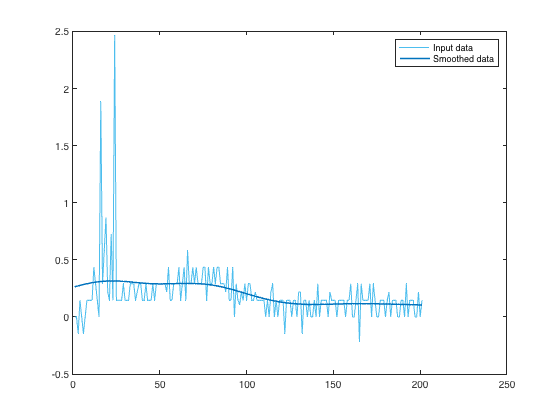

% Smooth input data
smoothedData2 = smoothdata(dataTable.rVel,"gaussian","SmoothingFactor",0.9);

% Display results
clf
plot(dataTable.rVel,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

newT.rVel = smoothedData2;

Max analogWrite command = 255

max motor.setM1Speed() command = 400

Since the motor command is a number out of 400, I need to divide the velocity by 400 to get a unit step response.

**THIS HAS NOTHING TO DO WITH THE VOLTAGE ON THE BATTERY.**

newT.fVel = newT.fVel/400; newT.rVel = newT.rVel/400;

#### Determine Transfer Function of Motor Command to Velocity

Find the steady state velocity of the motor (K)

K_rho = newT.fVel(newT.time > 0.4); KD_rho = newT.rVel(newT.time > 0.4);
K_rho = mean(K_rho), KD_rho = mean(KD_rho)

K_rho = 0.1771

KD_rho = 3.5276e-04

find 0.64 * K and the time constant to find sigma.

magAt64K_rho = max(newT.fVel(newT.fVel <= 0.64*K_rho+0.1*K_rho & newT.fVel >= 0.64*K_rho-0.1*K_rho))

magAt64K_rho = 0.1271

magAt64K_phi = max(newT.rVel(newT.rVel <= 0.64*KD_rho+0.1*KD_rho & newT.rVel >= 0.64*KD_rho-0.1*KD_rho))


magAt64K_phi =

  0×1 empty double column vector




TC_rho = newT.time(newT.fVel == max(magAt64K_rho));
TC_phi = newT.time(newT.rVel == max(magAt64K_phi));

Error using  == 
Arrays have incompatible sizes for this operation.

Related documentation

sigmaRho = mean(1./TC_rho);
sigmaPhi = mean(1./TC_phi);

With K and sigma, create the velocity and position transfer functions

s = tf('s');
velTF_rho = K_rho*(sigmaRho)/(s+sigmaRho);
velTF_rho.InputName = "motor command";
velTF_rho.OutputName = "velocity"

velTF_phi = KD_rho*(sigmaPhi)/(s+sigmaPhi);
velTF_phi.InputName = "motor command";
velTF_phi.OutputName = "velocity"

posTF_rho = velTF_rho*(1/s);
posTF_rho.InputName = "motor command";
posTF_rho.OutputName = "position";

posTF_phi = velTF_phi*(1/s);
posTF_phi.InputName = "motor command";
posTF_phi.OutputName = "position";

#### Plot the processed data (motor unit step response)

t2 = tiledlayout(1,2,"TileSpacing","compact",'Padding','tight');
xlabel(t2, 'Time (s)')
ylabel(t2, 'Velocity (rad/s)')
title(t2, 'Motor Unit Step Response (Scaled Motor Velocity Vs. Time)')

nexttile
plot(newT.time,newT.rVel)
title('Left Motor')
yline(magAt64K_phi,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_phi,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

nexttile
plot(newT.time,newT.fVel)
title('Right Motor')
yline(magAt64K_rho,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_rho,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

Turn the generated transfer functions into coefficient arrays for use in Simulink.

posNum_rho = posTF_rho.Numerator;       % Find the numerator coefficients
posNum_rho = posNum_rho{1};             % Convert the numerator to a the right form
posDen_rho = posTF_rho.Denominator;     % Find the denominator coefficients
posDen_rho = posDen_rho{1};             % Convert the denominator to a the right form

velNum_rho = velTF_rho.Numerator;       % Find the numerator coefficients
velNum_rho = velNum_rho{1};             % Convert the numerator to a the right form
velDen_rho = velTF_rho.Denominator;     % Find the denominator coefficients
velDen_rho = velDen_rho{1};             % Convert the denominator to a the right form

posNum_phi = posTF_phi.Numerator;       % Find the numerator coefficients
posNum_phi = posNum_phi{1};             % Convert the numerator to a the right form
posDen_phi = posTF_phi.Denominator;     % Find the denominator coefficients
posDen_phi = posDen_phi{1};             % Convert the denominator to a the right form

velNum_phi = velTF_phi.Numerator;       % Find the numerator coefficients
velNum_phi = velNum_phi{1};             % Convert the numerator to a the right form
velDen_phi = velTF_phi.Denominator;     % Find the denominator coefficients
velDen_phi = velDen_phi{1};             % Convert the denominator to a the right form

#### Compare the Transfer Function with Motor Response

figure
stepplot(velTF_phi,'m')
hold on
plot(newT.time,newT.rVel)
title("Left Motor Step Response")
legend('Transfer Function','Motor Response','Location','southeast')
hold off

stepplot(velTF_rho,'m')
hold on
plot(newT.time,newT.fVel)
title("Right Motor Step Response")
legend('Transfer Function','Motor Response','Location','southeast')
hold off

Not sure if I want to display both graphs together

% figure
% p1 = subplot(2,1,1);
% stepplot(p1,velTF_phi,'m');
% hold on
% plot(p1,newT.time,newT.rVel);
% hold off
% title("Left Motor Step Response")
% 
% p2 = subplot(2,1,2);
% stepplot(p2, velTF_rho,'m');
% hold on
% plot(p2, newT.time,newT.fVel);
% hold off
% title("Right Motor Step Response")
% lgd = legend('Transfer Function','Motor Response','Location','east');

#### Design a PI Controller to Regulate Position

Design a PI controller that achieves closed loop step response specifications of a rise time of 1 second and an overshoot of less than or equal to 12%, with zero steady state error.

figure

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/0.586984;

% PID tuning algorithm for linear plant model
[C_rho,pidInfo] = pidtune(posTF_rho,'PD',wc2);

% Clear Temporary Variables
clear wc2

% Get desired loop response
Response = getPIDLoopResponse(C_rho,posTF_rho,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on

% Display system response characteristics
disp(stepinfo(Response))

% Clear Temporary Variables
clear Response
KP_rho = C_rho.Kp, KD_rho = C_rho.Kd

KP_phiR = C_rho.Kp, KD_rho = C_rho.Kd

## Designing a controller for forward and rotational speed


$$\overline{V}_{a} = V_{a,1} + V_{a,2}$$



$$\Delta{V}_{a} = V_{a,1} - V_{a,2}$$


Va,1 and Va,2 are the voltage commands for the left and right motors

$\overline{V}_a$ is the magnitude of the combined voltage commands. Used for the forward speed $\dot{\rho}_d$ 

$\Delta V_a$ is the difference between the two voltage commands. Used for rotational speed $\dot{\phi}_d$

Forward velocity to voltage command:            $G_{\rho}(s) = \frac{\dot{\rho}(s)}{\overline{V}_a(s)}$

Rotational velocity to voltage command:        $G_{\phi}(s) = \frac{\dot{\phi}(s)}{\Delta V_a(s)}$